# Examen Final

Robot Planar 2 GDL

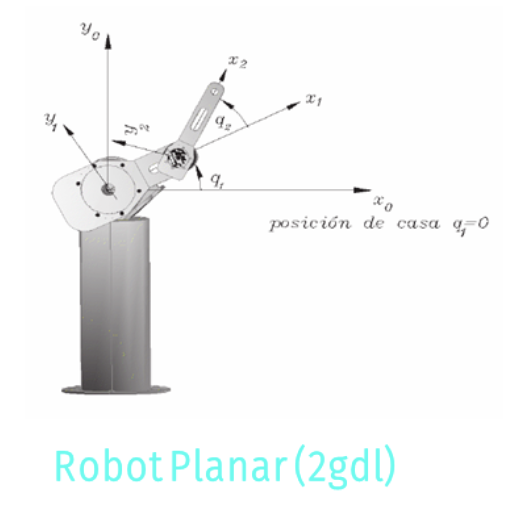

- Se comienza con una limpieza de pantalla y del workspace para un trabajo mucho mas eficiente, asi como tambien se inicializa el temporizador del programa.

%Limpieza de pantalla
clear all
close all
clc

%Temporizador
tic

- En esta parte se declaran las variables simbolicas para los angulos de cada articulacion, para las velocidades y aceleraciones de las articulaciones, para las masas y matrices de inercia, para las longitudes de los eslabones, las distancias al centro de masa de cada eslabon y las variables definidas de pi, la gravedad, aceleracion y cero.

%Declaración de variables simbólicas

%Angulos de cada articulación
syms th1(t) th2(t) t  
%Velocidades de cada articulación
syms th1p(t) th2p(t)  
%Aceleraciones de cada articulación
syms th1pp(t) th2pp(t) 
%Masas y matrices de Inercia
syms m1 m2  Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 
%l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms l1 l2 lc1 lc2  
syms pi g a cero

- Se generan los vectores para las coordenadas articulares, velocidades articulares y aceleraciones articulares.

 %Creamos el vector de coordenadas articulares
  Q= [th1; th2];
 disp('Coordenadas articulares');

Coordenadas articulares


 pretty (Q);

/ th1(t) \
|        |
\ th2(t) /



 
 %Creamos el vector de velocidades articulares
  Qp= [th1p; th2p];
 disp('Velocidades articulares');

Velocidades articulares


 pretty (Qp);

/ th1p(t) \
|         |
\ th2p(t) /




 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp; th2pp];
 disp('Aceleraciones articulares');

Aceleraciones articulares


 pretty (Qpp);

/ th1pp(t) \
|          |
\ th2pp(t) /



- Ya que el robot es planar, la configuracion del robot es para juntas rotacionales, y  es de dos grados de libertad. Cada elemento de la matriz corresponde a una articulación del robot y su tipo. En este caso, se está utilizando el valor `0` para indicar una junta rotacional.

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

- En esta parte comenzamos con las configuraciones de cada articulacion, en este caso tenemos dos. Declaramos la posicion de las articulaciones y las matrices de rotacion respecto a 0 y 1.

- Está relacionado con la descripción cinemática de un sistema mecánico compuesto por dos articulaciones. En particular, está modelando la posición y orientación de las articulaciones utilizando matrices de transformación homogénea. 

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) 0  -sin(th1);
           sin(th1) 0   cos(th1);
           0       -1         0];

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];

- Se crea un vector de ceros que se utiliza más adelante en la creación de matrices de transformación homogénea.

- Se crean matrices de transformación homogénea local (`A`), global (`T`), posiciones observadas desde el marco de referencia inercial (`PO`), y matrices de rotación observadas desde el marco de referencia inercial (`RO`).

- Este tramo de código realiza la cinemática directa de un sistema mecánico, calculando las matrices de transformación homogénea que describen la posición y orientación de cada articulación con respecto a un marco de referencia inercial. 

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end

Matriz de Transformación local A1


/ cos(th1(t)),  0, -sin(th1(t)),  0 \
|                                   |
| sin(th1(t)),  0,  cos(th1(t)),  0 |
|                                   |
|      0,      -1,       0,      l1 |
|                                   |
\      0,       0,       0,       1 /



Matriz de Transformación global T1


/ cos(th1(t)),  0, -sin(th1(t)),  0 \
|                                   |
| sin(th1(t)),  0,  cos(th1(t)),  0 |
|                                   |
|      0,      -1,       0,      l1 |
|                                   |
\      0,       0,       0,       1 /



/ cos(th1(t)),  0, -sin(th1(t)) \
|                               |
| sin(th1(t)),  0,  cos(th1(t)) |
|                               |
\      0,      -1,       0      /



/  0 \
|    |
|  0 |
|    |
\ l1 /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2


/ cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), -sin(th1(t)), l2 cos(th1(t)) cos(th2(t)) \
|                                                                                             |
| cos(th2(t)) sin(th1(t)), -sin(th1(t)) sin(th2(t)),  cos(th1(t)), l2 cos(th2(t)) sin(th1(t)) |
|                                                                                             |
|       -sin(th2(t)),            -cos(th2(t)),             0,          l1 - l2 sin(th2(t))    |
|                                                                                             |
\            0,                        0,                  0,                   1             /



/ cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), -sin(th1(t)) \
|                                                                 |
| cos(th2(t)) sin(th1(t)), -sin(th1(t)) sin(th2(t)),  cos(th1(t)) |
|                                                                 |
\       -sin(th2(t)),            -cos(th2(t)),             0      /



/ l2 cos(th1(t)) cos(th2(t)) \
|                            |
| l2 cos(th2(t)) sin(th1(t)) |
|                            |
\     l1 - l2 sin(th2(t))    /



- Este tramo de codigo calcula de manera analítica el Jacobiano lineal y angular de un sistema mecánico. El Jacobiano relaciona las velocidades lineales y angulares de las articulaciones con las velocidades lineales y angulares de los puntos y ejes en el espacio operativo del sistema.

- La lógica diferencial depende del tipo de articulación: rotacional o prismática. Se emplean productos cruz y asignaciones específicas según el tipo de junta para calcular las contribuciones al Jacobiano.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ -l2 cos(th2(t)) sin(th1(t)), -l2 cos(th1(t)) sin(th2(t)) \
|                                                          |
|  l2 cos(th1(t)) cos(th2(t)), -l2 sin(th1(t)) sin(th2(t)) |
|                                                          |
\              0,                    -l2 cos(th2(t))       /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, -sin(th1(t)) \
|                 |
| 0,  cos(th1(t)) |
|                 |
\ 1,       0      /




%Matriz de Jacobiano Completa
disp('Matriz de Jacobiano');

Matriz de Jacobiano


Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
pretty(Jacobiano);

/ -l2 cos(th2(t)) sin(th1(t)), -l2 cos(th1(t)) sin(th2(t)) \
|                                                          |
|  l2 cos(th1(t)) cos(th2(t)), -l2 sin(th1(t)) sin(th2(t)) |
|                                                          |
|              0,                    -l2 cos(th2(t))       |
|                                                          |
|              0,                      -sin(th1(t))        |
|                                                          |
|              0,                      cos(th1(t))         |
|                                                          |
\              1,                           0              /



- Una vez teniendo el jacobiano podemos pasar a obtener los vectores de velocidades lineales y angulares segun sea el caso.

- Estas líneas de código están realizando la transformación de las velocidades articulares (`Qp`) en velocidades lineales y angulares del sistema mediante el uso del Jacobiano. Los resultados (`V` y `W`) proporcionan información sobre cómo las velocidades de las articulaciones se traducen en velocidades lineales y angulares en diferentes puntos y ejes del sistema mecánico. 

%Obtenemos vectores de Velocidades Lineales y Angulares
 disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp);
 pretty(V);

/ - l2 cos(th2(t)) sin(th1(t)) th1p(t) - l2 cos(th1(t)) sin(th2(t)) th2p(t) \
|                                                                           |
|  l2 cos(th1(t)) cos(th2(t)) th1p(t) - l2 sin(th1(t)) sin(th2(t)) th2p(t)  |
|                                                                           |
\                          -l2 cos(th2(t)) th2p(t)                          /



 disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp);
 pretty(W);

/ -sin(th1(t)) th2p(t) \
|                      |
|  cos(th1(t)) th2p(t) |
|                      |
\        th1p(t)       /



- Este tramo de codigo se encarga de calcular la energía cinética de un sistema mecánico compuesto por dos eslabones. 

- Se obtienen las posiciones de los centros de masa de los eslabones 1 y 2 (`P01` y `P02w`) reemplazando las longitudes de los eslabones (`l1` y `l2`) por las posiciones de los centros de masa (`lc1` y `lc2`).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);
 P02=subs(P(:,:,2), l2, lc2);

- Estas matrices contienen información sobre la distribución de masa y la geometría de cada eslabón.

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 

- Se resta 1 para hablar solo de una articulacion.

%Eslabón 1

%Calculamos el jacobiano lineal de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ -l2 cos(th2(t)) sin(th1(t)), -l2 cos(th1(t)) sin(th2(t)) \
|                                                          |
|  l2 cos(th1(t)) cos(th2(t)), -l2 sin(th1(t)) sin(th2(t)) |
|                                                          |
\              0,                    -l2 cos(th2(t))       /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, -sin(th1(t)) \
|                 |
| 0,  cos(th1(t)) |
|                 |
\ 1,       0      /




%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
pretty(Jacobiano);

/ -l2 cos(th2(t)) sin(th1(t)), -l2 cos(th1(t)) sin(th2(t)) \
|                                                          |
|  l2 cos(th1(t)) cos(th2(t)), -l2 sin(th1(t)) sin(th2(t)) |
|                                                          |
|              0,                    -l2 cos(th2(t))       |
|                                                          |
|              0,                      -sin(th1(t))        |
|                                                          |
|              0,                      cos(th1(t))         |
|                                                          |
\              1,                           0              /




%Obtenemos vectores de Velocidades Lineales y Angulares
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
pretty(V1);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify (Jw_a1*Qp(1));
pretty(W1);

/    0    \
|         |
|    0    |
|         |
\ th1p(t) /





%Eslabón 2
%Ya lo calculamos previamente al multiplicar la matriz jacobiana por Qp

%%%%%%%%%%%%%%%%%%%%%%%%
%Calculamos la energía cinética para cada eslabon

- Se calcula la energía cinética del eslabón 1 (`K1`) mediante la fórmula de energía cinética que incluye la translación y rotación del eslabón.

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

              2
Izz1 |th1p(t)|
---------------
       2



- Se calcula la energía cinética del eslabón 2 (`K2`)

%Eslabón 2
V2_Total= V+cross(W,P02);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W)'*(I2*W);
disp('Energía Cinética en el Eslabón 3');

Energía Cinética en el Eslabón 3


K2= simplify (K2);
pretty (K2);

          /
Izz2 #2   | __
------- + | m2 (lc2 cos(th2(t)) th1p(t) + l2 cos(th1(t)) cos(th2(t)) th1p(t) - l2 sin(th1(t)) sin(th2(t)) th2p(t))
   2      \

   /            2                2                2 \ \     /
   | #2 #3 |lc2|    #2 #6 #3 |l2|    #1 #5 #4 |l2|  | |     | __
   | ------------ + -------------- - -------------- | |/2 + | m2 (lc2 sin(th2(t)) th1p(t) + l2 cos(th2(t)) sin(th1(t)) th1p(t) + l2
   \  lc2 th1p(t)     l2 th1p(t)       l2 th2p(t)   / /     \

                                    /            2                2                2 \ \
                                    | #2 #4 |lc2|    #2 #3 #5 |l2|    #1 #6 #4 |l2|  | |     Iyy2 #1 cos(th1(t)) #6
   cos(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------------- + -------------- | |/2 + ----------------------
                                    \  lc2 th1p(t)     l2 th1p(t)       l2 th2p(t)   / /                2

                                 __                                                         2  

- Finalmente, se obtiene la energía cinética total del sistema (`K_Total`), sumando las contribuciones de ambos eslabones.

K_Total= simplify (K1+K2);
pretty (K_Total);

                    /
Izz1 #1   Izz2 #1   | __
------- + ------- + | m2 (lc2 cos(th2(t)) th1p(t) + l2 cos(th1(t)) cos(th2(t)) th1p(t) - l2 sin(th1(t)) sin(th2(t)) th2p(t))
   2         2      \

   /            2                2                2 \ \     /
   | #1 #3 |lc2|    #1 #6 #3 |l2|    #2 #5 #4 |l2|  | |     | __
   | ------------ + -------------- - -------------- | |/2 + | m2 (lc2 sin(th2(t)) th1p(t) + l2 cos(th2(t)) sin(th1(t)) th1p(t) + l2
   \  lc2 th1p(t)     l2 th1p(t)       l2 th2p(t)   / /     \

                                    /            2                2                2 \ \
                                    | #1 #4 |lc2|    #1 #3 #5 |l2|    #2 #6 #4 |l2|  | |     Iyy2 #2 cos(th1(t)) #6
   cos(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------------- + -------------- | |/2 + ----------------------
                                    \  lc2 th1p(t)     l2 th1p(t)       l2 th2p(t)   / /                2

                                 __                    

- Este tramo de codigo se encarga de calcular la energía potencial para cada uno de los eslabones de un sistema mecánico compuesto por dos eslabones. 

- Se obtienen las alturas (`h1` y `h2`) de los centros de masa de los eslabones 1 y 2, respectivamente, con respecto al eje vertical (ya que es el que corresponde a nuestro robot).

- Se calcula la energía potencial para cada eslabón (`U1` y `U2`) utilizando la fórmula de la energía potencial gravitatoria, donde `m1` y `m2` son las masas de los eslabones, `g` es la aceleración debido a la gravedad y `h1` y `h2` son las alturas de los centros de masa de los eslabones 1 y 2, respectivamente.

- Se calcula la energía potencial total del sistema (`U_Total`) sumando las contribuciones de los dos eslabones.

- "La energía potencial es una medida de la energía almacenada en el sistema debido a su posición en un campo gravitatorio y es una parte importante en el análisis de la energía en sistemas mecánicos."

%Calculamos la energía potencial para cada uno de los eslabones

%Obtenemos las alturas respecto a la gravedad
 h1= P01(2); %Tomo la altura paralela al eje y
 h2= P02(2); %Tomo la altura paralela al eje y

 %Calculamos la energía potencial total
 U1=m1*g*h1;
 U2=m2*g*h2;
 U_Total= U1 + U2;

- Una vez que tenemos ciertos valores podemos calcular el Lagrangiano y el modelo de energia.

- El Lagrangiano, denotado comúnmente como L, es una función que describe la diferencia entre la energía cinética (K) y la energía potencial (U) de un sistema mecánico. Se define matemáticamente como: L=K−U; el Lagrangiano es una cantidad importante en la mecánica clásica y se utiliza en la formulación de las ecuaciones de movimiento de un sistema físico.

- El modelo de energía, denotado como H, también conocido como la función Hamiltoniana, es la suma de la energía cinética (K) y la energía potencial (U) de un sistema mecánico. Se define matemáticamente como: H=K+U; la función Hamiltoniana es una herramienta útil en el análisis de sistemas físicos, especialmente en mecánica analítica y física teórica.

 %Obtenemos el Lagrangiano
 Lagrangiano= simplify (K_Total-U_Total);
 pretty (Lagrangiano);

%Modelo de Energía
 H= simplify (K_Total+U_Total);
 pretty (H)

- Para las ecuaciones de movimento, usamos el Lagrangiano derivado con respecto a la primera coordenada generalizada de velocidad.

- Se calcula el torque para la primera articulación (`t1`). Para ello, se multiplica el vector de derivadas de la velocidad en la primera coordenada generalizada (`dQ1`) por el vector de velocidad generalizada (`Qd`). Luego, se resta la derivada del Lagrangiano con respecto a la primera coordenada generalizada (`th1`). Este proceso se realiza de acuerdo con las ecuaciones de Euler-Lagrange, que son fundamentales en la formulación de las ecuaciones de movimiento de sistemas físicos.

- Este tramo de código proporciona una forma de calcular el torque (o fuerza generalizada) para una articulación específica de un sistema mecánico, lo que es esencial para modelar y simular el comportamiento dinámico del sistema. Las ecuaciones de Euler-Lagrange ayudan a describir cómo las fuerzas y ��torques actúan sobre un sistema y cómo esto influye en su movimiento y evolución temporal.

- Torque 1

  %%%%%%%%%%%%%%%%%%%%%%Ecuaciones de Movimiento%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 Qd=[th1p(t); th2p(t); th1pp(t); th2pp(t)];

 %Obtenemos las derivadas de la velocidad en la primera coordenada
 %generalizada
 dQ1=[diff(diff(Lagrangiano,th1p), th1),diff(diff(Lagrangiano,th1p), th2),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 2 posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p),diff(diff(Lagrangiano,th1p), th2p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 2 velocidades articulaciones
 
 %Definimos el torque 1
 t1= dQ1*Qd- diff(Lagrangiano, th1)

- Torque 2

 %Obtenemos las de derivadas de la velocidad en la segunda coordenada
 %generalizada

 dQ2=[diff(diff(Lagrangiano,th2p), th1),diff(diff(Lagrangiano,th2p), th2),... %Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th2p), th1p),diff(diff(Lagrangiano,th2p), th2p)];%Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 velocidades articulaciones

 %Definimos el torque 2
 t2= dQ2*Qd- diff(Lagrangiano, th2)

%Generación del Modelo Dinámico en forma matricial

- Se construye la matriz de inercia (M) del sistema, que describe cómo las aceleraciones articulares (θ¨) se relacionan con los torques (τ) aplicados a las articulaciones. La matriz de inercia se calcula tomando las derivadas segundas de los torques con respecto a las aceleraciones articulares, se deriva parcialmente los torques respecto a las aceleraciones articulares, formando así la matriz de inercia M.

%Matriz de Inercia
%Extraemos coeficientes de aceleraciones
M=[diff(t1, th1pp), diff(t1, th2pp);...
   diff(t2, th1pp), diff(t2, th2pp)];
rank (M);
M=M(t)

- Se calculan las fuerzas centrípetas y de Coriolis (C) del sistema. Estas fuerzas surgen debido a la aceleración angular de las articulaciones y su interacción con la velocidad angular. Se calculan mediante la matriz Mp, que se deriva parcialmente respecto a las velocidades articulares (θ˙) y se multiplica por las velocidades articulares.

- Las fuerzas centrípetas son fuerzas radiales, teniendo un signo contrario a las fuerzas centrífugas. La fuerza de Coriolis representa una desviación del movimiento de translación debido a su componente en rotación. 

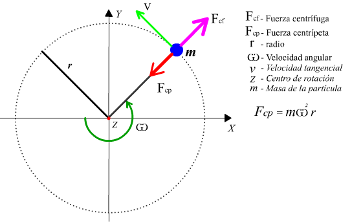

 %Fuerzas Centrípetas y de Coriolis
 %Definimos Mp
 M11=[diff(M(1,1),th1), diff(M(1,1),th2)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 
 M12=[diff(M(1,2),th1), diff(M(1,2),th2)]*Qp;

 M21=[diff(M(2,1),th1), diff(M(2,1),th2)]*Qp;
 M22=[diff(M(2,2),th1), diff(M(2,2),th2)]*Qp;

  Mp=[M11, M12;...
     M21, M22];


%Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp

%Definimos dk

dk=[diff(k, th1); diff(k, th2)];

%Fuerzas centrípetas y de Coriolis
 C= Mp*Qp-dk

- Se calcula el par gravitacional (G) del sistema, que representa la fuerza ejercida por la gravedad sobre las articulaciones. Esto se hace sustituyendo las velocidades y aceleraciones articulares por cero y evaluando los torques resultantes

 %Par Gravitacional
 %se sustituyen las velocidades y aceleraciones por 0
 r=cero;
 a1=subs(t1, th1p, r);
 a2=subs(a1, th2p, r);
 a3=subs(a2, th1pp,r);
 a4=subs(a3, th2pp,r);
 %Torque gravitacional en el motor 1
 G1=a4;

 
 b1=subs(t2, th1p, r);
 b2=subs(b1, th2p, r);
 b3=subs(b2, th1pp,r);
 b4=subs(b3, th2pp,r);
 %Torque gravitacional en el motor 2
 G2=b4;


% Vector de par gravitacional
G=[G1;G2]

 toc

Elapsed time is 20.305708 seconds.
